# MPC Distrubance Rejection

## Bluetooth

%% Connect to the HC-06 module
close all;
bt_connected = 0; % change it to 1 after connecting to bluetooth
if (bt_connected == 0)
    clear; 
    bt = Bluetooth("HC-06",1); % connects to the bluetooth module as a serial communication object
    fopen(bt); % initialize the serial object
end

flushoutput(bt);
fprintf(bt,num2str(0));

## System

mcart = 0.493;
mpend = 0.312;
Ipend = 0.00024;
l = 0.04;
f = 0.01;
kt = 0.11;
R = 10;
r = 0.0335;
g = 9.81;
inputGain = 2*kt/(R*r);

% State Space
A = [0 1 0 0;
    0 (-(Ipend + mpend*l^2)*f)/(Ipend*(mcart+mpend)+ mcart*mpend*l^2) mpend^2*g*l^2/(Ipend*(mcart+mpend)+ mcart*mpend*l^2) 0;
    0 0 0 1;
    0 -mpend*l*f/(Ipend*(mcart+mpend)+ mcart*mpend*l^2) mpend*g*l*(mcart+mpend)/(Ipend*(mcart+mpend)+ mcart*mpend*l^2) 0];
B = [0; (Ipend+mpend*l^2)/(Ipend*(mcart+mpend)+ mcart*mpend*l^2);
    0; mpend*l/(Ipend*(mcart+mpend)+ mcart*mpend*l^2)].*1/inputGain;
C= [1 0 0 0];
D = 0;

% Discrete system
sys = ss(A,B,C,D);
sys_d = c2d(sys, 0.200, 'zoh');
fprintf("Rank of ctrb discrete system = %i", rank(ctrb(sys_d)));

Rank of ctrb discrete system = 4


A_d = sys_d.A;
B_d = sys_d.B;
C_d = sys_d.C;

## LQR

lqr_weight = [10 1 1e7 1e4];
Q_lqr = diag(lqr_weight);
R_lqr = 1;
%Kpos =  -31.62, K_xdot = -145.97, Ktheta = 3310, KthetaDot = 325.4;

% Discrete controller
K_d = dlqr(A_d, B_d, Q_lqr, R_lqr)

K_d =    -0.0004   -0.0120    5.5755    0.3717


% COntinuous controller
K = lqr(A,B,Q_lqr,R_lqr)

K = 	1.0e+03 *

   -0.0032   -0.0453    3.1818    0.1034


%K = [0 0 6000 100];

## Closed Loop System

% Discrete closed loop
% disp("Discrete LQR step")
sys_cld = ss(A_d-B_d*K_d, B_d, C_d, D);
% step(sys_cld);
% eig(A_d-B_d*K_d)

% disp("Continuous LQR step")
sys_cl = ss(A-B*K, B, C, D);
% step(sys_cl);
sys_cl = c2d(sys_cl, 0.005, 'zoh');

A=sys_cl.A;
B=sys_cl.B;
C=sys_cl.C;

## Augmented State Space 

state_n = size(A, 1);
A_new = [A zeros(state_n,1); C 1];
B_new = [B; 0];
C_new = [C 0; zeros(1,state_n) 1];
W_new = [B*K;-1 0 0 0];

input_n = size(B_new, 2);

## MPC Formulation

N = 8;
R = 1; % Control penalty
Q = diag([1e6; 10]);  % output = [position; integral of error]
Qbar = [];%blkdiag(Q,Q);
Rbar = [];%blkdiag(R,R);
Tbar = [];
W_bar_temp = [];
W_bar = [];
% Tbar = [C_new*A_new;C_new*A_new^2];
% Sbar = [C_new*B_new zeros(2,1);C_new*A_new*B_new C_new*B_new];
% Wbar = [C_new*W_new;C_new*W_new + C_new*A_new*W_new];
for i=1:N
    Tbar = [Tbar;C_new*A_new^i];
    Qbar = blkdiag(Qbar,Q);
    Rbar = blkdiag(Rbar,R);
end
Sbar = [C_new*B_new zeros(2,1) zeros(2,1) zeros(2,1) zeros(2,1) zeros(2,1) zeros(2,1) zeros(2,1);
        C_new*A_new*B_new C_new*B_new zeros(2,1) zeros(2,1) zeros(2,1) zeros(2,1) zeros(2,1) zeros(2,1);
        C_new*(A_new^2)*B_new  C_new*A_new*B_new  C_new*B_new zeros(2,1) zeros(2,1) zeros(2,1) zeros(2,1) zeros(2,1);
        C_new*(A_new^3)*B_new C_new*(A_new^2)*B_new C_new*A_new*B_new C_new*B_new zeros(2,1) zeros(2,1) zeros(2,1) zeros(2,1);
        C_new*(A_new^4)*B_new C_new*(A_new^3)*B_new C_new*(A_new^2)*B_new C_new*A_new*B_new C_new*B_new zeros(2,1) zeros(2,1) zeros(2,1);
        C_new*(A_new^5)*B_new C_new*(A_new^4)*B_new C_new*(A_new^3)*B_new C_new*(A_new^2)*B_new C_new*A_new*B_new C_new*B_new zeros(2,1) zeros(2,1);
        C_new*(A_new^6)*B_new C_new*(A_new^5)*B_new C_new*(A_new^4)*B_new C_new*(A_new^3)*B_new C_new*(A_new^2)*B_new C_new*A_new*B_new C_new*B_new zeros(2,1);
        C_new*(A_new^7)*B_new C_new*(A_new^6)*B_new C_new*(A_new^5)*B_new C_new*(A_new^4)*B_new C_new*(A_new^3)*B_new C_new*(A_new^2)*B_new C_new*A_new*B_new C_new*B_new];

Wbar = [C_new*W_new;
        C_new*W_new + C_new*A_new*W_new;
        C_new*W_new + C_new*A_new*W_new + C_new*(A_new^2)*W_new;
        C_new*W_new + C_new*A_new*W_new + C_new*(A_new^2)*W_new + C_new*(A_new^3)*W_new;
        C_new*W_new + C_new*A_new*W_new + C_new*(A_new^2)*W_new + C_new*(A_new^3)*W_new + C_new*(A_new^4)*W_new;
        C_new*W_new + C_new*A_new*W_new + C_new*(A_new^2)*W_new + C_new*(A_new^3)*W_new + C_new*(A_new^4)*W_new + C_new*(A_new^5)*W_new;
        C_new*W_new + C_new*A_new*W_new + C_new*(A_new^2)*W_new + C_new*(A_new^3)*W_new + C_new*(A_new^4)*W_new + C_new*(A_new^5)*W_new + C_new*(A_new^6)*W_new;
        C_new*W_new + C_new*A_new*W_new + C_new*(A_new^2)*W_new + C_new*(A_new^3)*W_new + C_new*(A_new^4)*W_new + C_new*(A_new^5)*W_new + C_new*(A_new^6)*W_new + C_new*(A_new^7)*W_new];
H = (Rbar+Sbar'*Qbar*Sbar);
H = (H+H')/2;

G = [tril(eye(N*input_n));-tril(eye(N*input_n))];
S = zeros(2*N*input_n,5);
W = 12*ones(2*N,1);

iter = 500;
r = 0.15*ones(iter,1);
%r = 2*square([1:iter+N+1]/200);

Xact = [];
Uopt = [];
Usys = [];
X = [0;0;0;0;0];
U = 0;
lqr_prev = 0;
v_prev = 0;
v = 0;
U_disturb = 0;

warning('off','all')
options = optimoptions('quadprog');
options.Display = 'none';
lqr_u = [];
lqr_voltage = 0;
% pitch = [];
Uprev = 0;
ii=1;
tic
while (ii<iter)
    flushinput(bt); 
    fscanf(bt); 
    rawdata = fscanf(bt);
    X = parsedata(rawdata);
%    lqr_voltage = (X(6)/255)*12;
%    lqr_u = [lqr_u lqr_voltage];
    Usys=[Usys X(5)];
%     pitch = [pitch rad2deg(X(2))];
%    lqr_u=[lqr_u X(6)];
    v = v_prev + X(1) - r(ii);
    X=[X(1:4,1); v];
    Xact(:,ii) = X;

    Rbarref = [r(ii);0];
    Rbarref = repmat(Rbarref,N,1);
    RR = [r(ii) 0 0 0];
    
    f = 2*(X'*Tbar'*Qbar*Sbar - Rbarref'*Qbar*Sbar - RR*Wbar'*Qbar*Sbar); 
    
    Z = quadprog(H,f,G,W+S*X,[],[],[],[],[],options);
    
    Uopt(ii) = Z(1) - U_disturb;
    U = Uopt(ii);

    pos = X(1);
    pitch = X(3);
    flushoutput(bt); 
    fprintf(bt,num2str(U));
    ii=ii+1;
    v_prev = v;
    
end
toc

Elapsed time is 15.659732 seconds.


Xact(:,ii+1) = X;
flushoutput(bt);
fprintf(bt,num2str(0));

## Plotting

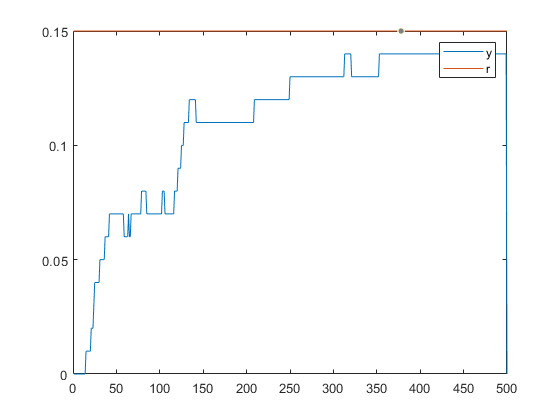

%% Plotting
y=C_new*Xact;
figure
plot([1:iter],y(1,1:iter),[1:iter],r(1:iter))
legend('y','r')

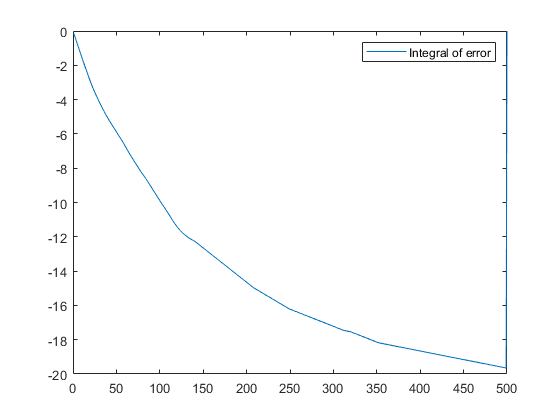

% figure
% plot([1:iter],pitch(1,1:iter),[1:iter],0*ones(1,iter))
% legend('Angle w/ MATLAB','w/o MATLAB')
figure
plot([1:iter],y(2,1:iter))
legend('Integral of error')

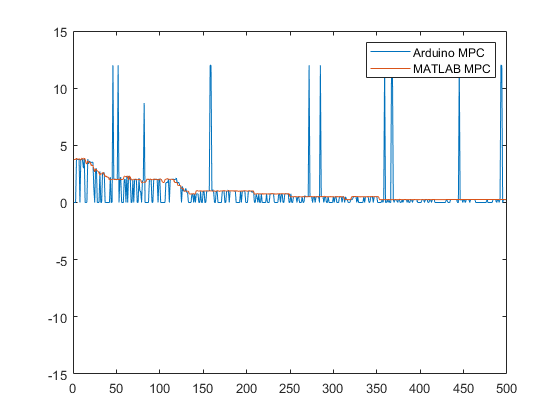

figure
plot([1:iter-1], Usys(1, 1:iter-1))
hold on
plot([1:iter-1],Uopt(1,1:iter-1))
hold off
ylim([-15 15])
legend('Arduino MPC','MATLAB MPC')

%figure
%plot([1:iter-1], lqr_u(1, 1:iter-1))

% % Usys = Usys(Usys<255 & Usys>-255);
% plot(Usys*12/255)
% hold off
% legend('MPC Control', 'Arduino MPC')